# FFT Applications - Special Cases of Noisy and Time-varying Signals

## Noisy signals - using power spectral density function (e.g. the Welch method)

Theoretical Fourier spectrum of noisy signal is flat-and-constant (*white* noise) or flat-and-nonconstant - monotically decaying or increasing (*color* noise, e.g. *pink* or *blue*). But in practice FFT spectrum of any noise is not flat but "peaky". In order to minimize spurious peaks and make the spectrum of noisy signal easier for interpretation* signal here-noise there*, any signal with noise should be processed as follows (calculation of a *mean* FFT spectrum):

- cut the signal into shorter, overlapping fragments,

- perform fragments windowing,

- optionally append them at the end with zeros,

- perform FFT upon each signal fragment,

- scale the result taking into account the window applied, 

- raise to the second power the FFT spectrum magnitude (calculation of power, do not of amplitude spectrum),

- calculate mean power spectrum, i.e. average all power spectra,

- divide the result by sampling frequency and obtain the **power spectral density function (PDF)**, typically used for noisy signals.

**Read description and run some demos of the Matlab functions **`pwelch()`** and **`periodogram()`**.**

## Time-varying signals - short-time Fourier transform (STFT)

When the signal has frequency content varying in time (as in the case of frequency modulated signals), its sines/cosines oscillates with different frequencies in different moments. Therefore, again, the signal should be cutted into shorter, overlaping fragments and many consecutive FFT spectra should be computed and stored. Each of them should show us instantaneous spectrum with local frequency content (with momentum, not mean values of frequencies). Putting all spectra one-by-one into a matrix, one obtains a so-called short-time Fourier transform (STFT) (sequence of DFT spectra calculated for short signal fragments). Looking to them we should see how signal frequencies are changing in time.

**Read description and run demos of the Matlab function **`spectrogram()`**.**

## Analyzed signal

In this laboratory we will "investigate" the following signals:

- x1(n) - sinusoid embeded in white Gaussian noise with the help of Welch method (`pwelch(), periodogram()`),

- sinusoid with linear (x2(n)) and sinusoidal (x3(n)) frequency modulation with the help of STFT (`spectrogram()`).   

**Analyze the Matlab code**. Run it. Observe shapes of signals x1(n), x2(n), x3(n) - do their zooming. Set different strength of random disturbance.

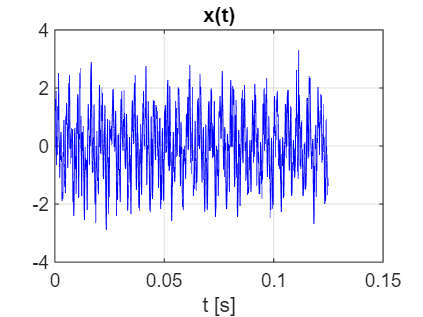

clear all; close all;

% Parameters
fs = 8000;              % sampling ratio (Hz)
T  = 3;                 % time duration in seconds
N  = round(T*fs);       % number of signal samples, 100 or 1000
dt=1/fs; t=dt*(0:N-1);  % time scaling
n = 1:1000;             % indexes of signal samples to observe

% Signal
x1 = sin(2*pi*200*t) + sin(2*pi*800*t);                              % 2xSIN 
x2 = sin( 2*pi*( 0*t + 0.5*((1/T)*fs/4)*t.^2 ) );                    % LFM
fm=0.5; x3 = sin(2*pi*((fs/4)*t - (fs/8)/(2*pi*fm)*cos(2*pi*fm*t))); % SFM
x = x1 + 0.5*randn(1,N);                                             % signal choice
figure; plot(t(n),x(n),'b-'); xlabel('t [s]'); title('x(t)'); grid;  % figure

## Analysis method

As stated above during spectral analysis of, both, noisy and time-varying signals, the signal is cut into shorter overlapping fragments and FFT spectra are computed for them all. After that in noisy case one mean spectrum is calculated, while in time-varying case all the spectra are combined into a *time-frequency* matrix (matrix of spectra computed for consecutive signal fragments), presenting changing of signal frequency content in time.

**Become familar with the Matlab code.** The following denotations are used in it:

- `Mwind` - length of the signal fragment (i.e. the obserwation window length)

- `Mstep` - window shift (`Mwind-Mstep` = number of overlapping samples`)`

- `Mfft - FFT` length (`Mfft-Mwind `= number of zeros appended at signal end`)` 

Run the code for all three signals with different settings of `Mwind, Nstep `and` Mfft.`

- Choosing small value of `Mwind `causes that the FFT spectra have low-frequency resolution but they are more local and less smoothed due to the signal change.

- Choosing larger value of `Mwind `causes that the FFT spectra have better frequency resolution but they are less local and are more smoothed due to the signal change. 

- Observe that the PSD periodogram (Welch) method works well for sinusoid disturbed by noise.

- Note that the time-frequency spectrogram (STFT) method works well for signals with frequencies varying in time. 

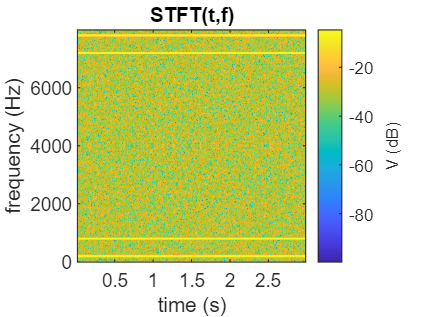

% FFT spectrum
Mwind = 256; Mstep=16; Mfft=2*Mwind;  Many = floor((N-Mwind)/Mstep)+1;
x = x1 + 0.5*randn(1,N);                            % signal choice
t = (Mwind/2+1/2)*dt + Mstep*dt*(0:Many-1);         % time
f = fs/Mfft*(0:Mfft-1);                             % frequency    
w = hamming( Mwind )';                              % window choice
X1 = zeros(Mfft,Many); X2 = zeros(1,Mfft);          % STFT, PSD initialization 
for m = 1 : Many                                    % MAIN PROCESSING LOOP---------
    bx = x( 1+(m-1)*Mstep : Mwind+(m-1)*Mstep );    % cut signal fragment 
    bx = bx .* w;                                   % do its "windowing"
    X = fft( bx, Mfft )/sum(w); % FFT with (Mfft-Mwind) zeros appending and scaling
    X1(1:Mfft,m) = abs(X);                          % single FFT spectrum
    X2 = X2 + abs(X).^2;                            % accumulated Welch PSD 
  % semilogy(f,X2/m); xlabel('f [Hz]'); title('mean( |X(f)|^2 )'); pause
end                                                 % LOOP END---------------------
X1 = 20*log10( X1 );                                % to decibels
X2 = (1/Many)*X2/fs;                                % PSD normalization

figure;               % Short-Time Fourier Transform
imagesc(t,f,X1);      % matrix of changing "amplitude" DFT spectrum as an image
c=colorbar; c.Label.String = 'V (dB)'; ax = gca; ax.YDir = 'normal';
xlabel('time (s)'); ylabel('frequency (Hz)'); title('STFT(t,f)');

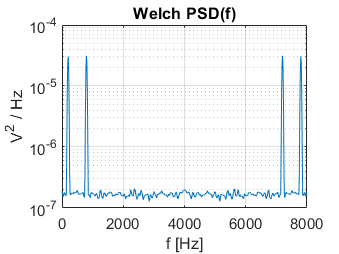


figure;               % Welch Power Spectrum Density (PSD)
semilogy(f,X2); grid; title('Welch PSD(f)'); xlabel('f [Hz]'); ylabel('V^2 / Hz');

Verify obtained results with outputs of corresponding Matlab functions:

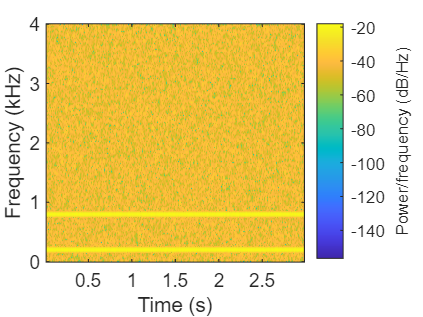

% Matlab functions
figure; spectrogram(x,Mwind,Mwind-Mstep,Mfft,fs,'yaxis');  % Short-Time FT (STFT)

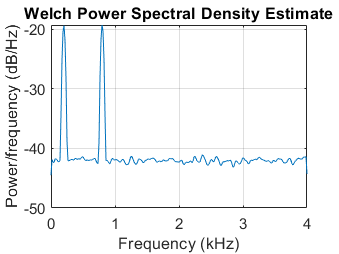

figure; pwelch(x,Mwind,Mwind-Mstep,Mfft,fs);               % Welch PSD

**Modify the program.** Record your own speech and analyze it using `pwelch()` and `spectrogram()`.